clc
clear

addpath("c:/git/UQ4PDE_Homeworks/Homework 4/functions/example functions/")
addpath("c:/git/UQ4PDE_Homeworks/Homework 4/functions/")
addpath("c:/git/UQ4PDE_Homeworks/Sparse Grids MATLAB/")



x = linspace(0, 1, 100);
w = 2;
N = 2;
type = 'HC';
cmax = 5;
f = @(x) f_gaussian(x);
[M, ~] = size(generateMultiIndexSet(N, w, type));
condition = zeros(cmax, 1);
M

M = 5

%{
tic
for c=1:cmax
    M = c*M;
    [coeff, indxset, DTD] = getLegendreCoefficientsND(f, w, N, type, M);
    condition(c) = cond(DTD);
end
toc
%}

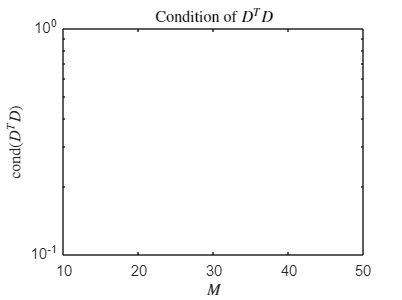


figure()
semilogy(10:10:(cmax*10), condition, 'x--')
xlim([10 10*cmax])
title('Condition of $D^TD$', 'Interpreter', 'latex')
xlabel('$M$', 'Interpreter', 'latex')
ylabel('cond$(D^TD)$', 'Interpreter', 'latex')